% Presetting
PosExtract=[0; 0; 0; 1];

% 2-DoF Manipulator Forward Kinematics
syms L1 L2 theta1 theta2;

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = 0;
T01 = DHParameter(a0, alpha0, d1, theta1)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm1 to Arm2
a1 = L1;
alpha1 = 0;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2)

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & L_{1}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm2 to Endpoint
a2 = L2;
alpha2 = 0;
d3 = 0;
theta3 = 0;
T2E = DHParameter(a2, alpha2, d3, theta3)

$$T2E = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Base to Endpoint
T0E = simplify(T01*T12*T2E)

$$T0E = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Position of Endpoint according to Base Coordinate
p0E=T0E*PosExtract

$$p0E = \left(\begin{array}{c} L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)\\ 0\\ 1 \end{array}\right)$$

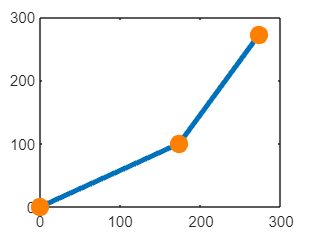

p =   Line - 속성 있음:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [1 0.5000 0]
              XData: [0 173.2051 273.2051]
              YData: [0 100.0000 273.2051]

  모든 속성 표시


%  2-DoF Manipulator Kinematics test by plot graph
theta1=pi/6;
theta2=pi/6;
L1=200;
L2=200;

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = 0;
T01 = DHParameter(a0, alpha0, d1, theta1);

% Arm1 to Arm2
a1 = L1;
alpha1 = 0;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2);

% Arm2 to Endpoint
a2 = L2;
alpha2 = 0;
d3 = 0;
theta3 = 0;
T2E = DHParameter(a2, alpha2, d3, theta3);

% Base to Each Coordinate
T02 = T01*T12;
T0E = T01*T12*T2E;

% Position of Each Coordinate according to Base Coordinate
p01=T01*PosExtract;
p02=T02*PosExtract;
p0E=T0E*PosExtract;

% plot
p = plot([p01(1,1), p02(1,1), p0E(1,1)],[p01(2,1), p02(2,1), p0E(2,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0]